1(A)

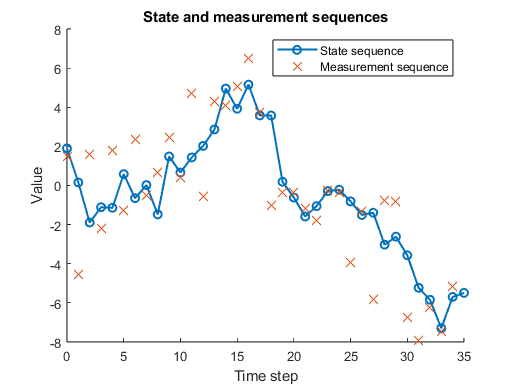

% Set model parameters
A = 1;
Q = 1.5;
H = 1;
R = 3;
x_0 = 2;
P_0 = 8;

% Generate state and measurement sequences
N = 35;
X = genLinearStateSequence(x_0,P_0,A,Q,N);
Y = genLinearMeasurementSequence(X, H, R);

% Plot state and measurement sequences
figure;
hold on;
plot(0:length(X)-1, X, '-o', 'LineWidth', 1.5);
plot(0:length(Y)-1, Y, 'x', 'MarkerSize', 10);
xlabel('Time step');
ylabel('Value');
legend('State sequence', 'Measurement sequence');
title('State and measurement sequences');

1(B)

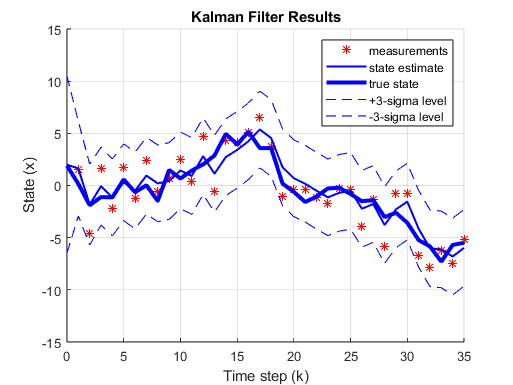

% Perform Kalman filtering to estimate the state sequence
[x_kk,P_kk] = kalmanFilter(Y,x_0,P_0,A,Q,H,R);
figure;
hold on, grid on;
% Plot the measurements, state estimate, true state, and +3/-3 sigma levels
p1 = plot([1:N], Y, '*r', 'DisplayName','measurements');
p2 = plot([0:N], [x_0 x_kk], 'b', 'LineWidth',1.5, 'DisplayName','state estimate');
p3 = plot([0:N], X, 'b', 'LineWidth',3, 'DisplayName','true state');
p3.Color = [p3.Color 0.2];
p4 = plot([0:N], [x_0 x_kk] + 3*sqrt([P_0 P_kk(:)']), '--b', 'DisplayName','+3-sigma level');
p5 = plot([0:N], [x_0 x_kk] - 3*sqrt([P_0 P_kk(:)']), '--b', 'DisplayName','-3-sigma level');
xlabel('Time step (k)');
ylabel('State (x)');
title('Kalman Filter Results');
legend([p1, p2, p3, p4, p5], 'Location', 'northeast');

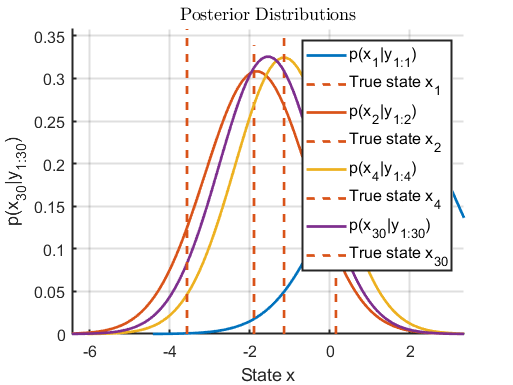


% Plot the posterior distributions for specific time steps
idx = [1, 2, 4, 30];

figure('Name', 'Posterior Distributions')
hold on
grid on
set(gca, 'FontName', 'Helvetica', 'FontSize', 12, 'LineWidth', 1.5)
clr = get(gca, 'ColorOrder');

for i = 1:numel(idx)
    xmu = x_kk(idx(i));% mean of the posterior distribution
    xvar = P_kk(idx(i));% variance of the posterior distribution
    x = linspace(xmu - 4 * sqrt(xvar), xmu + 4 * sqrt(xvar), 100);
    y = (1 / sqrt(2 * pi * xvar)) * exp(-(x - xmu).^2 / (2 * xvar));
    name = sprintf('p(x_{%d}|y_{1:%d})', idx(i), idx(i));
    p1 = plot(x, y, 'LineWidth', 2, 'DisplayName', name);

    xtrue = X(idx(i) + 1);% true state at the time step
    p2 = plot([xtrue, xtrue], [0, max(y) * 1.1], '--', 'LineWidth', 2, 'Color', [clr(2,:), 0.5], 'DisplayName', sprintf('True state x_{%d}', idx(i)));
    
    p1.Color = clr(i,:);
    p1.LineStyle = '-';
    p2.LineStyle = '--';

    ylim([0, max(y) * 1.1])
    xlim([x(1), x(end)])
    xlabel('State x')
    ylabel(name)
    title('Posterior Distributions', 'Interpreter', 'Latex')
    legend('Location', 'northeast', 'FontSize', 12)
end

1(C)

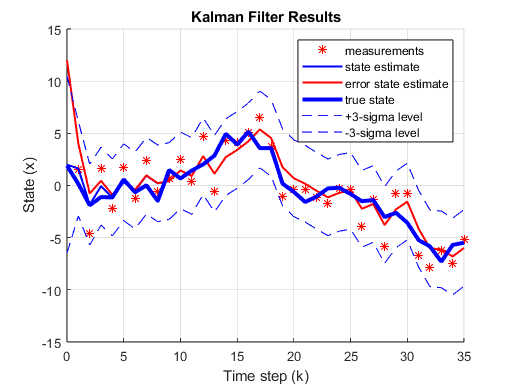


[x_kk,P_kk] = kalmanFilter(Y,x_0,P_0,A,Q,H,R);
% Kalman filter with an starting point of 12
[x_kk1,P_kk1] = kalmanFilter(Y,12,P_0,A,Q,H,R);
figure;
hold on, grid on;
% Plot the measurements as red asterisks
p1 = plot([1:N], Y, '*r', 'DisplayName','measurements');
% Plot the estimated state as a blue line
p2 = plot([0:N], [x_0 x_kk], 'b', 'LineWidth',1.5, 'DisplayName','state estimate');
% Plot the estimated state with the arbitrary starting point as a red line
p22 = plot([0:N], [12 x_kk1], 'r', 'LineWidth',1.5, 'DisplayName','error state estimate');
% Plot the true state as a blue line with lower opacity
p3 = plot([0:N], X, 'b', 'LineWidth',3, 'DisplayName','true state');
p3.Color = [p3.Color 0.2];
% Plot the upper 3-sigma level as a dashed blue line
p4 = plot([0:N], [x_0 x_kk] + 3*sqrt([P_0 P_kk(:)']), '--b', 'DisplayName','+3-sigma level');
% Plot the lower 3-sigma level as a dashed blue line
p5 = plot([0:N], [x_0 x_kk] - 3*sqrt([P_0 P_kk(:)']), '--b', 'DisplayName','-3-sigma level');
xlabel('Time step (k)');
ylabel('State (x)');
title('Kalman Filter Results');
%legend for the plot
legend([p1, p2, p22, p3, p4, p5], 'Location', 'northeast');

1(D)

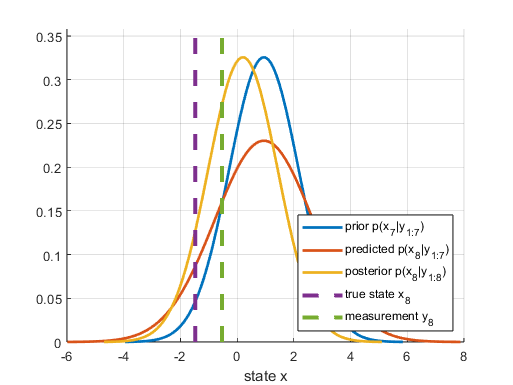

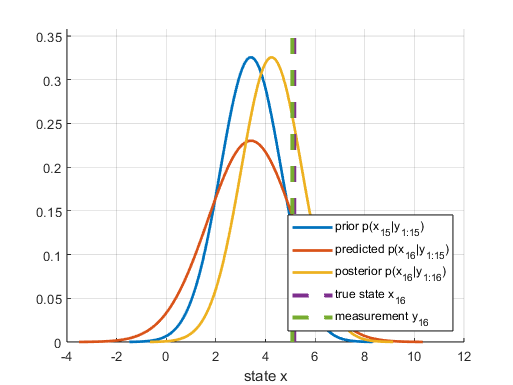

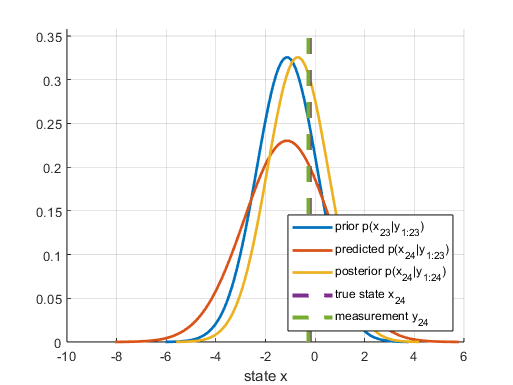


idx = [8, 16, 24];
% Run the Kalman filter to get the predicted and filtered estimates
[x_kk,P_kk,x_kkm1,p_kkm1] = kalmanFilter_pred(Y,x_0,P_0,A,Q,H,R);
for i=1:numel(idx)
    
    figure;
    hold on, grid on;
    % Get the mean and covariance of the prior distribution for the selected state
    mu_prior = x_kk(idx(i)-1);
    P_prior  = P_kk(idx(i)-1);
    % Create a Gaussian curve for the predicted distribution and plot it
    x = linspace(mu_prior - 4 * sqrt(P_prior), mu_prior + 4 * sqrt(P_prior), 100);
    y = (1 / sqrt(2 * pi * P_prior)) * exp(-(x - mu_prior).^2 / (2 * P_prior));
    p1 = plot(x,y, 'LineWidth',2, 'DisplayName', sprintf('prior p(x_{%d}|y_{1:%d})',idx(i)-1,idx(i)-1) );
    %below are the same operation mainly, change the interested variable
    mu_pred = x_kkm1(idx(i));
    P_pred  = p_kkm1(idx(i));
    x = linspace(mu_pred - 4 * sqrt(P_pred), mu_pred + 4 * sqrt(P_pred), 100);
    y = (1 / sqrt(2 * pi * P_pred)) * exp(-(x - mu_pred).^2 / (2 * P_pred));    
    p2 = plot(x,y, 'LineWidth',2, 'DisplayName', sprintf('predicted p(x_{%d}|y_{1:%d})',idx(i),idx(i)-1) );
    
    mu_post = x_kk(idx(i));
    P_post  = P_kk(idx(i));
    x = linspace(mu_post - 4 * sqrt(P_post), mu_post + 4 * sqrt(P_post), 100);
    y = (1 / sqrt(2 * pi * P_post)) * exp(-(x - mu_post).^2 / (2 * P_post));       

    p3 = plot(x,y, 'LineWidth',2, 'DisplayName', sprintf('posterior p(x_{%d}|y_{1:%d})',idx(i),idx(i)) );
    
    xtrue = X(idx(i)+1);
    p4 = plot([xtrue,xtrue], [0,max(y)*1.1],'--', 'LineWidth',3, 'Color', [clr(4,:) 0.5],'DisplayName',sprintf('true state x_{%d}',idx(i)));
    
    xmean = Y(idx(i));
    p4 = plot([xmean,xmean], [0,max(y)*1.1],'--', 'LineWidth',3, 'Color', [clr(5,:) 0.5],'DisplayName',sprintf('measurement y_{%d}',idx(i)));
    
    ylim([0,max(y)*1.1])
    xlabel 'state x'
    legend('Location','southeast')
end

1(e)

% General parameters
N = 10000;
% calculate state and measurement sequences
X = genLinearStateSequence(x_0,P_0,A,Q,N);
Y = genLinearMeasurementSequence(X, H, R);
% filter data
%Run the Kalman filter on the measurement sequence specifically to get v
%matrix for analysis.
[x_k_k, P_k_k, v] = kalmanFilter_vsk(Y, x_0, P_0, A, Q, H, R);


mean(x_k_k)

ans = -38.9389

mean(v)

ans = -0.0157

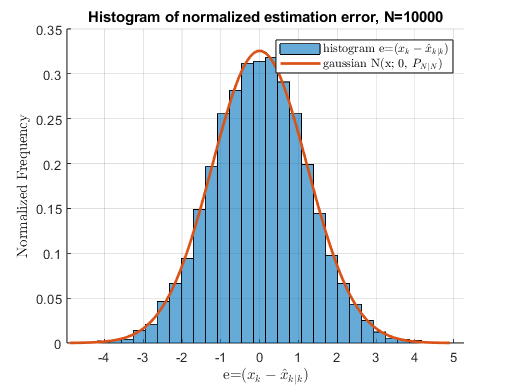

% Plot a histogram of the normalized estimation error
figure;
hold on, grid on;

histogram( (x_k_k-X(:,2:end)), 30 ,'DisplayName','histogram e=($x_k-\hat{x}_{k|k}$) ','Normalization','pdf');


x = linspace(0 - 4 * sqrt(P_k_k(:,:,end)), 0 + 4 * sqrt(P_k_k(:,:,end)), 100);
y = (1 / sqrt(2 * pi * P_k_k(:,:,end))) * exp(-(x - 0).^2 / (2 * P_k_k(:,:,end))); 
p3 = plot(x,y, 'LineWidth',2, 'DisplayName', sprintf('gaussian N(x; 0, $P_{N|N})$') );

xlabel('e=($x_k-\hat{x}_{k|k}$)','Interpreter','Latex')
ylabel('Normalized Frequency','Interpreter','Latex')
title 'Histogram of normalized estimation error, N=10000'
legend('Interpreter','Latex')

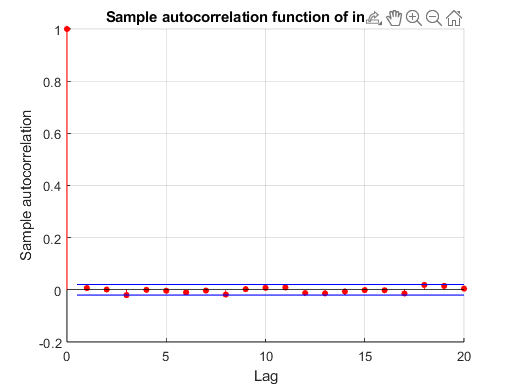



% Plot the sample autocorrelation function of the innovation sequence using
% economical library
figure;
hold on, grid on;
autocorr(v)
xlabel 'Lag', ylabel 'Sample autocorrelation', title 'Sample autocorrelation function of innovation'